load("test_functions2.mat","-mat")

f = f2;
gradf = gradf2;
Hessf = Hessf2;

c1 = 1e-4;
rho = 0.8;
btmax = 1;
em = eps();
h = 10*sqrt(em);
disp_int = [-20 20]

disp_int =    -20    20


x_start = x0;%[-10 -5]'
[xk,fk,gradfk_norm,k,xseq] = newton_general(x_start,f,gradf,Hessf,kmax,tolgrad,c1,rho,btmax,true,"FW","FW",h)

Hessf_k = 1.0e+04 *

    3.2002    0.2000
    0.2000    0.0200


xk =     1.0000
    0.9999


fk = 2.0053e-09

gradfk_norm = 2.4851e-13

k = 24

xseq =    -5.0000   -4.9988   -2.2909   -2.2885   -0.3462   -0.3442    0.6763    0.6780    0.9655    0.9677    1.0056    1.0006    0.9998    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -5.0000   24.9881   -2.0833    5.2371   -3.6519    0.1185   -0.5836    0.4597    0.8497    0.9365    1.0098    1.0013    0.9997    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


## Contour plot

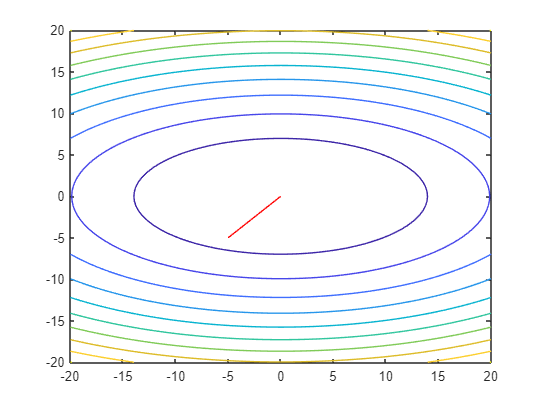

f1_meshgrid = @(X,Y)reshape(f1([X(:),Y(:)]'),size(X));
fcontour(f1_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

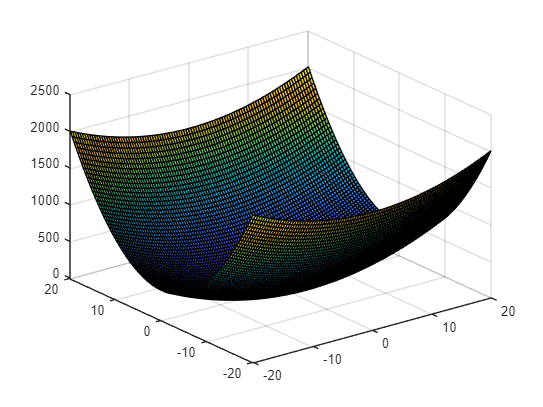

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f1_surf = f1_meshgrid(X,Y);

surf(X,Y,f1_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f1_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off